# Labeling Point Clouds

In order to train an object detector or any supervised deep learning model, you need to first label your data. For this series, we label cars, cones, and barrels using the [Lidar Labeler app](https://www.mathworks.com/help/lidar/ref/lidarlabeler-app.html). 

Before labeling, you may wish to split your data into train and test dataset. This helps when we get to deep learning and have to validate our model.

pcd_files = dir("../1. Understanding and Processing Point Clouds\parkingLot_Edit\*.pcd");

test_data = pcd_files(1:366);
train_data = pcd_files(367:807);                                                                    

if ~exist("../parkingLotTrain", 'dir')
    mkdir("../parkingLotTrain");
end

if ~exist("../parkingLotTest", 'dir')
    mkdir("../parkingLotTest");
end

for i=1:length(train_data)
    fileName = fullfile(train_data(i).folder, train_data(i).name);
    copyfile(fileName, "../parkingLotTrain");
end

for i=1:length(test_data)
    fileName = fullfile(test_data(i).folder, test_data(i).name);
    copyfile(fileName, "../parkingLotTest");
end

You can start a new labeling session by running the 'lidarLabeler' command below

lidarLabeler

or by selecting the Lidar Labeler app from the 'APPS' tab

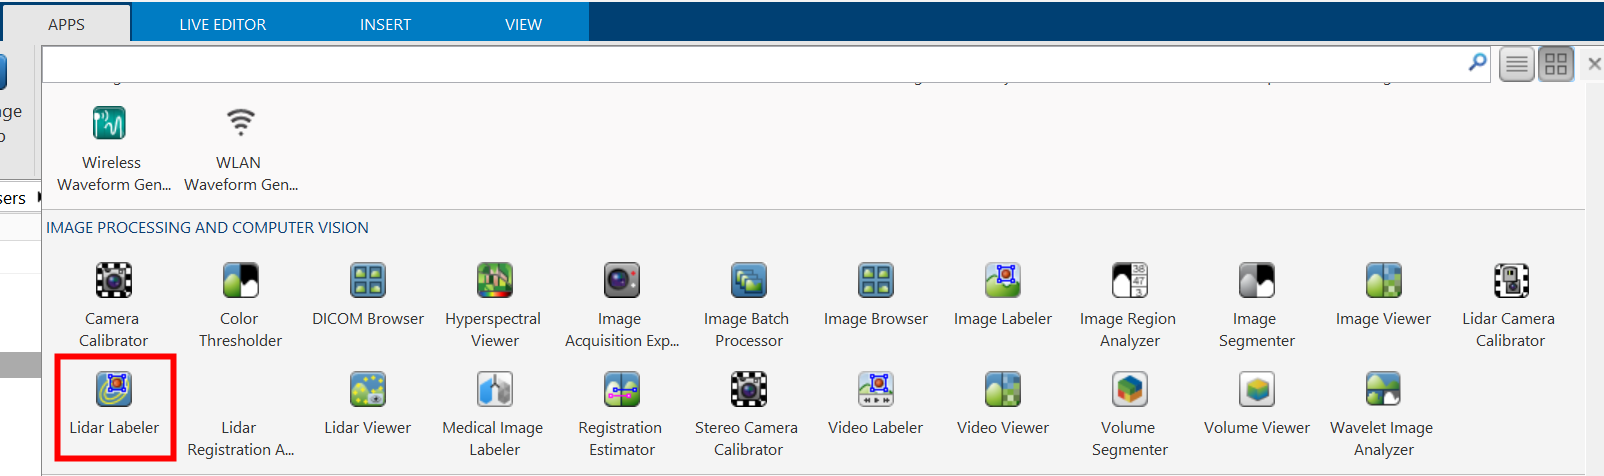

When the applicaiton opens, use the 'Import' button to import the point cloud data and, if applicable, any labels you may have already created. In the video, we import a Point Cloud Sequence through .PCD files, but there are many different data formats and filetypes supported, as shown below.

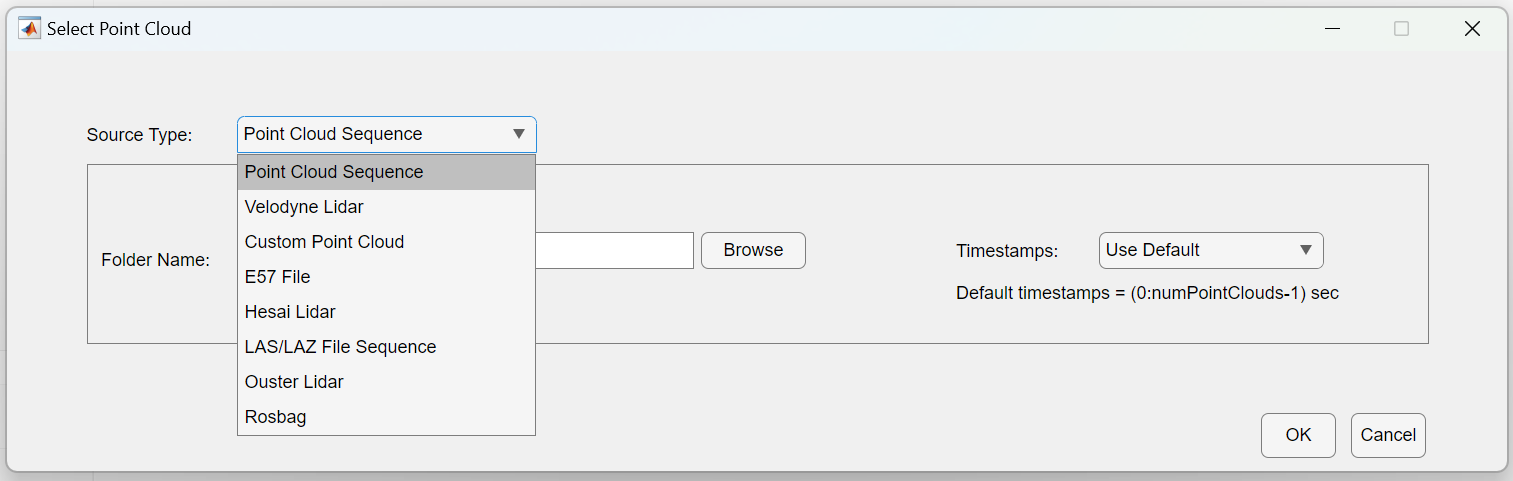

Specify the 'parkingLotTrain' folder to load the cropped point clouds into the app. Once it has loaded, you're ready to start labeling! The options on the toolstrip allow you to change how you see the point cloud or how your bounding boxes are made

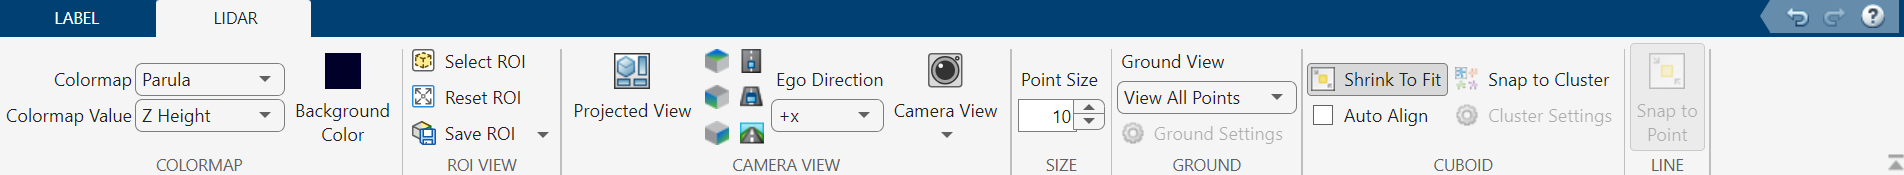

And the 'ROI Labels' Panel to the left will be where you actually create the label definitions

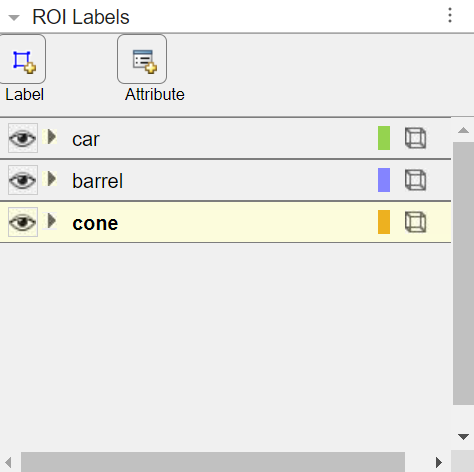

When you're ready to start labeling, simply choose the label you want to use, hover over the desired point cloud with your mouse, and click! A bounding box will automatically be created based on the cluster you had highlighted. When you're done, export your labels from the app to the MATLAB Workspace or to a file. They will be exported as a *groundTruthLidar* object. 

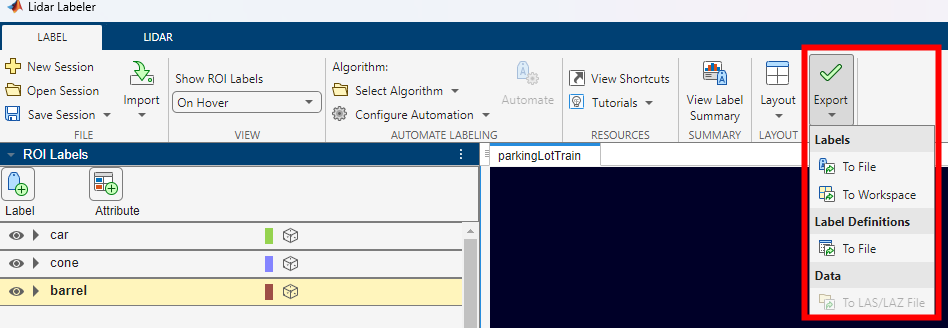

While using the app, you have the option to save your session so that you can come back and finish labeling later. Doing this will save the location of your data as well as any labels you have created already. 

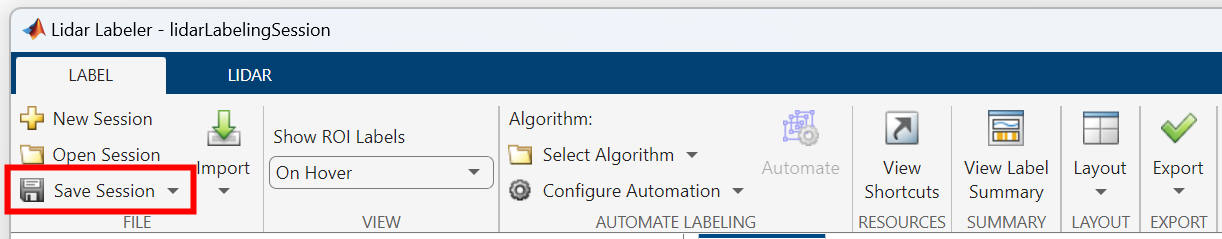

You can open a saved session by passing the name of the .mat file that contains the saved session, as shown below, or by selecting 'Open Session' from the app.

You can also use `groundTruthLidar` objects (often in a variable named gTruth) to share the labeling progress with others. First, use the code below to update gTruth so the variable shows where the data is stored on the new computer using the [`changeFilePaths`](https://www.mathworks.com/help/vision/ref/groundtruth.changefilepaths.html) function.

load gTruth;
oldPath = gTruth.DataSource.SourceName;
% Fill this in with the location of the parkingLot folder. 
newPath = "C:\Users\gracew\GitLab\lidar-series\parkingLotTrain";
alternativePaths = {[oldPath newPath]};
unresolvedPaths = changeFilePaths(gTruth,alternativePaths);
save gTruth;

Then, open the Lidar Labeler using the existing labels

lidarLabeler(gTruth);